% Convex Optimization
% Hw 5
% Q5_b

clear;
clc;
close all

% initialization
run('cens_fit_data.m');

cvx_begin
    variables c_hat(n) P(K-M)
    minimize(sum_square(y-X(:,1:M)'*c_hat)+sum_square(P-X(:,M+1:K)'*c_hat))
    subject to
        P >= D % Modeling censored data with their lower bound
cvx_end

 
Calling SDPT3 4.0: 179 variables, 97 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 97
 dim. of socp   var  = 104,   num. of socp blk  =  2
 dim. of linear var  = 75
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.2e+01|3.3e+00|1.3e+04| 4.939536e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.553|0.552|2.8e+01|1.5e+00|6.8e+03| 1.325069e+02 -4.727462e+01| 0:0:00| chol  1  1 
 2|0.426|0.445|1.6e+01|8.3e-01|4.4e+03| 2.213833e+02 -1.222557e+02| 0:0:00| chol  1  1 
 3|0.391|0.500|9.7e+00|4.2e-01|2.9e

% Ignoring Censored data
cvx_begin
    variable c_ls(n)
    minimize(sum_square(y-X(:,1:M)'*c_ls))
cvx_end

 
Calling SDPT3 4.0: 27 variables, 21 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 21
 dim. of socp   var  = 27,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|1.4e+00|1.4e+02| 1.837117e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|4.8e-06|3.8e-03|1.2e+01| 1.474423e+00 -9.786794e+00| 0:0:00| chol  1  1 
 2|1.000|0.955|6.9e-08|5.4e-04|4.1e-01|-7.473875e-01 -1.136421e+00| 0:0:00| chol  1  1 
 3|1.000|0.820|1.3e-08|1.3e-04|2.4e-02|-1.015238e+00 -1.032181e

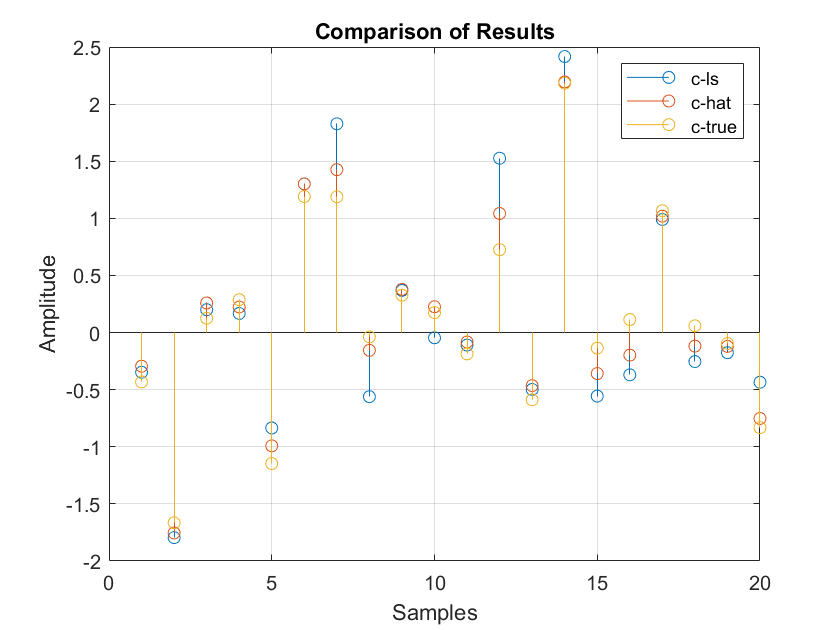

% comparing results
figure()

stem(c_ls);
hold on
stem(c_hat)
hold on
stem(c_true)
title("Comparison of Results")
grid on
xlabel('Samples')
ylabel('Amplitude')
legend('c-ls','c-hat','c-true')

% Definition of Errors:
hat_rel_err = norm(c_true-c_hat)/norm(c_true);
cls_rel_err = norm(c_true-c_ls)/norm(c_true);

disp('Relative Erros:')

Relative Erros:


disp('1: ')

1: 


hat_rel_err

hat_rel_err = 0.1784

disp('2: ')

2: 


cls_rel_err

cls_rel_err = 0.3907